## Regional air freight aircraft Specification

% Fixed Parameter
g = 9.81; % Gravity (kg/m^2)
Datum   = 11.5; % From Tip to Datum (m)
Crew    = 2;


% Measurments 
FuselageL = 24.2; % Fuselage length (m)
Wingspan  = 19.25; % (m)
WingA     = 32.51; % Wing Area (m^2)
ArW       = Wingspan^2/WingA; % Aspect Ratio of Wing
CabinL    = 14.1; % Cabin Length (m)

% Performance
OEW        = 8812; % (kg)
MTOW       = 16020*g; % (kg)
MaxPayload = 5290; % (kg)
MaxFuel    = 3600; % (kg)
DesignFuel = 1918; % (kg)
MLW        = 15570; % (kg)

% Aircraft Masses
Wings          = 1573.6; % (kg)
HorizontalTail = 334.5; % (kg)
VerticalFin    = 289.9; % (kg)
Fuselage       = 5714; % (kg)

% Loading Gear loading Limits
FrontLG = 370; % Front Landing Gear (kg)
MainLG  = 18000; % Main Landing Gear (kg)

% Engine and Power
EngineW_1   = 450; % Engine 1 Weight (kg)
EngineW_2   = 450; % Engine 2 Weight (kg)
Fuelconsump = 0.485; % Fuel Consumption (lb/hp/hr)
SThrust     = 18550 * 2; % Static Thrust both Engine (N ISA)
PropD       = 3.5; % Propeller Diameter (m), variable pitch

Conversions 

Feet  = 3.2808399; % Conversion from meters to feet
Knots = 1.94384449; % conversion form m/s to kts

## Centre Of Gravity Limits

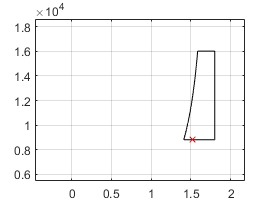

% Weight array and COG calculation
weight = 8812:10:16020;

RearG  = Datum + 1.8; % Rear Gear location on x axis
FrontG = Datum - 7.5; % Front Gear location on x axis
for   i=1:length(weight)
    cg = ((369.99 * (FrontG-RearG)./weight)+RearG) - Datum;
end
figure(1)
plot(cg, weight, 'color','black') % Front structrual limit 
hold off
%Graphing
hold on
plot([1.58510448413690 1.8], [16020 16020], 'color','black') % MTOW
plot([1.8 1.8], [8812 16020], 'color','black') % Rear Gear
plot([1.40952031320926 1.8], [8812 8812], 'color','black')
grid on; grid minor

xlim([-0.46 2.18])
ylim([5454 18631])

plot(1.525, 8812, 'rx')

Altitudes 

% Air Density at Different Altitudes (kg/m^3)
Ad_0    = 1.224995968060217;
Ad_2000 = 1.154899172335768;
Ad_4000 = 1.0879259769692413;
Ad_6000 = 1.023980271180393;
Ad_8000 = 0.9629659441889794;

% Temperature at Different Altitudes (Kelvin)
T_0    = 288.2;
T_2000 = 284.2;
T_4000 = 280.2;
T_6000 = 276.3;
T_8000 = 272.3;

% Speed of Sound at Different Altitudes (m/s)
SS_0    = 340.2957888; 
SS_2000 = 337.9443584;
SS_4000 = 335.5839872;
SS_6000 = 333.201264;
SS_8000 = 330.8051296;

## Take-Off Distance 

% Parameters
Re       = 55000000 % Reynalds number

Re = 55000000

e        = (1.78 * (1 - (0.045 * (ArW^0.68)))) - 0.64; % Oswalds Efficency Factor
k        = 1/(pi * ArW * e); % Ground induced drag
GR_Cl    = 0.035; % Ground run lift coefficient on dry asphalt
LcH      = 35 * 0.3048; % lift off Clearance height
Power    = 1625000 * 2; % Power of both engines (W)
Clmax_20 = 1.408; % Maximum lift Coefficient (Javafoil)
Clmin    = GR_Cl/(2 * k); % Mimimum Ground run lift coefficient
Clmin_3D = (Clmin/(1+(Clmin/(pi * ArW * e)))); % Minimum 3D Coefficient of lift 
Clmax_3D = (Clmax_20/(1+(Clmax_20/(pi * ArW * e)))) % Maximum 3d Coefficient of lift

Clmax_3D = 1.3352

Cldelta  = Clmax_3D - Clmin_3D; % Differnce between Max and Min Lift Coefficient
Cd0 = 0.07508; % Coefficient of drag at 20 Deg flap Deflection (Javafoil)
Cd       = Cd0 + (k*(Clmax_20^2)); % Drag

% Take off at 0ft (Sea Level)

Vstall0 = sqrt((2 * MTOW * g)/(Ad_0 * Clmax_3D * WingA)) % Stall Speed VStall (m/s)

Vstall0 = 240.8073


LminV0 = 1.1 * Vstall0; % Minimum lift off Velocity (m/s)
LminK0 = LminV0 * 1.94384449 % Minimum lift off Velocity (kts)

LminK0 = 514.9011


ToV0   = 1.2 * Vstall0; % Take off Velocity (m/s)
ToK0   = ToV0 * 1.94384449 % Take off Velocity (kts)

ToK0 = 561.7103


Vr0       = (1.2 * 1.05)/ 1.1 * Vstall0; % Rotational Take off Velocity 
Clmin_To0 = (MTOW/(0.5 * Ad_0 * (Vr0^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR0    = -(MTOW/(g * Ad_0 * WingA)) * (1/(Cd - (GR_Cl * Clmin_3D))) * log(1 - (Cd - (GR_Cl * Clmin_3D)/(SThrust/MTOW - GR_Cl) * Clmin_To0)) % Ground Run Distance (m)

GroudR0 = 458.2771

GroundRft0 = GroudR0 * 3.2808399 % Ground Run Distance (ft)

GroundRft0 = 1.5035e+03


M0       = LminV0 / SS_0 % Mach Number at 0ft

M0 = 0.7784

PropE0   = (2.97984 * M0) - (6.92675 * M0^2) + (19.1836 * M0^3) - (20.94595 * M0^4) % Propellor efficency (Function at Mach number)

PropE0 = -0.5195

ThrustA0 = (PropE0 * Power) / LminV0 % Thrust Avalible (N)

ThrustA0 = -6.3745e+03

Di0      = 0.5 * Ad_0 * LminV0^2 * Cd * WingA % initial Drag

Di0 = 2.1219e+05

AngLo0   = asin(ThrustA0 - Di0/MTOW) % Lift off Angle Gamma

AngLo0 = -1.5708 + 9.4534i


LoAP0   = (((MTOW / WingA) * AngLo0) / (Ad_0 * g * Cldelta)) + (LcH / AngLo0) % Lift off Air Phase (m)

LoAP0 = -7.0922e+02 + 4.2661e+03i

ToD0    = GroudR0 + LoAP0 % Total Take off Distance (m)

ToD0 = -2.5094e+02 + 4.2661e+03i

ToDft0  = ToD0 * Feet % Total Take off Distance (ft)

ToDft0 = -8.2331e+02 + 1.3996e+04i


% Take off at 2000ft

Vstall2000 = sqrt((2 * MTOW * g)/(Ad_2000 * Clmax_3D * WingA)) % Stall Speed VStall (m/s)

Vstall2000 = 248.0076


LminV2000 = 1.1 * Vstall2000; % Minimum lift off Velocity (m/s)
LminK2000 = LminV2000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK2000 = 530.2970


ToV2000   = 1.2 * Vstall2000; % Take off Velocity (m/s)
ToK2000   = ToV2000 * 1.94384449 % Take off Velocity (kts)

ToK2000 = 578.5058


Vr2000       = (1.2 * 1.05)/ 1.1 * Vstall2000; % Rotational Take off Velocity 
Clmin_To2000 = (MTOW/(0.5 * Ad_2000 * (Vr2000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR2000    = -(MTOW/(g * Ad_2000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_3D))) * log(1 - (Cd - (GR_Cl * Clmin_3D)/(SThrust/MTOW - GR_Cl) * Clmin_To2000)); % Ground Run Distance (m)
GroundRft2000 = GroudR2000 * 3.2808399 % Ground Run Distance (ft)

GroundRft2000 = 1.5948e+03


M2000       = LminV2000 / SS_2000 % Mach Number at 2000ft

M2000 = 0.8073

PropE2000   = (2.97984 * M2000) - (6.92675 * M2000^2) + (19.1836 * M2000^3) - (20.94595 * M2000^4) % Propellor efficency (Function at Mach number)

PropE2000 = -0.9117

ThrustA2000 = (PropE2000 * Power) / LminV2000 % Thrust Avalible (N)

ThrustA2000 = -1.0862e+04

Di2000      = 0.5 * Ad_2000 * LminV2000^2 * Cd * WingA % initial Drag

Di2000 = 2.1219e+05

AngLo2000   = asin(ThrustA2000 - Di2000/MTOW) % Lift off Angle

AngLo2000 = -1.5708 + 9.9863i


LoAP2000   = (((MTOW / WingA) * AngLo2000) / (Ad_2000 * g * Cldelta)) + (LcH / AngLo2000) % Lift off Air Phase (m)

LoAP2000 = -7.5224e+02 + 4.7802e+03i

ToD2000    = GroudR2000 + LoAP2000 % Total Take off Distance (m)

ToD2000 = -2.6615e+02 + 4.7802e+03i

ToDft2000  = ToD2000 * Feet % Total Take off Distance (ft)

ToDft2000 = -8.7318e+02 + 1.5683e+04i


% Take off at 4000ft

Vstall4000 = sqrt((2 * MTOW * g)/(Ad_4000 * Clmax_3D * WingA)) % Stall Speed VStall (m/s)

Vstall4000 = 255.5273


LminV4000 = 1.1 * Vstall4000; % Minimum lift off Velocity (m/s)
LminK4000 = LminV4000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK4000 = 546.3759


ToV4000   = 1.2 * Vstall4000; % Take off Velocity (m/s)
ToK4000   = ToV4000 * 1.94384449 % Take off Velocity (kts)

ToK4000 = 596.0464


Vr4000       = (1.2 * 1.05)/ 1.1 * Vstall4000; % Rotational Take off Velocity 
Clmin_To4000 = (MTOW/(0.5 * Ad_4000 * (Vr4000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR4000    = -(MTOW/(g * Ad_4000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_3D))) * log(1 - (Cd - (GR_Cl * Clmin_3D)/(SThrust/MTOW - GR_Cl) * Clmin_To4000)); % Ground Run Distance (m)
GroundRft4000 = GroudR4000 * 3.2808399 % Ground Run Distance (ft)

GroundRft4000 = 1.6930e+03


M4000       = LminV4000 / SS_4000 % Mach Number at 4000ft

M4000 = 0.8376

PropE4000   = (2.97984 * M4000) - (6.92675 * M4000^2) + (19.1836 * M4000^3) - (20.94595 * M4000^4) % Propellor efficency (Function at Mach number)

PropE4000 = -1.4001

ThrustA4000 = (PropE4000 * Power) / LminV4000 % Thrust Avalible (N)

ThrustA4000 = -1.6189e+04

Di4000      = 0.5 * Ad_4000 * LminV4000^2 * Cd * WingA % initial Drag

Di4000 = 2.1219e+05

AngLo4000   = asin(ThrustA4000 - Di4000/MTOW) % Lift off Angle

AngLo4000 = -1.5708 + 10.3853i


LoAP4000   = (((MTOW / WingA) * AngLo4000) / (Ad_4000 * g * Cldelta)) + (LcH / AngLo4000) % Lift off Air Phase (m)

LoAP4000 = -7.9852e+02 + 5.2774e+03i

ToD4000    = GroudR4000 + LoAP4000 % Total Take off Distance (m)

ToD4000 = -2.8251e+02 + 5.2774e+03i

ToDft4000  = ToD4000 * Feet % Total Take off Distance (ft)

ToDft4000 = -9.2686e+02 + 1.7314e+04i


% Take off at 6000ft

Vstall6000 = sqrt((2 * MTOW * g)/(Ad_6000 * Clmax_3D * WingA)) % Stall Speed VStall (m/s)

Vstall6000 = 263.3851


LminV6000 = 1.1 * Vstall6000; % Minimum lift off Velocity (m/s)
LminK6000 = LminV6000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK6000 = 563.1776


ToV6000   = 1.2 * Vstall6000; % Take off Velocity (m/s)
ToK6000   = ToV6000 * 1.94384449 % Take off Velocity (kts)

ToK6000 = 614.3756


Vr6000       = (1.2 * 1.05)/ 1.1 * Vstall6000; % Rotational Take off Velocity 
Clmin_To6000 = (MTOW/(0.5 * Ad_6000 * (Vr6000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR6000    = -(MTOW/(g * Ad_6000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_3D))) * log(1 - (Cd - (GR_Cl * Clmin_3D)/(SThrust/MTOW - GR_Cl) * Clmin_To6000)); % Ground Run Distance (m)
GroundRft6000 = GroudR6000 * 3.2808399 % Ground Run Distance (ft)

GroundRft6000 = 1.7987e+03


M6000       = LminV6000 / SS_6000 % Mach Number at 6000ft

M6000 = 0.8695

PropE6000   = (2.97984 * M6000) - (6.92675 * M6000^2) + (19.1836 * M6000^3) - (20.94595 * M6000^4) % Propellor efficency (Function at Mach number)

PropE6000 = -2.0078

ThrustA6000 = (PropE6000 * Power) / LminV6000 % Thrust Avalible (N)

ThrustA6000 = -2.2523e+04

Di6000      = 0.5 * Ad_6000 * LminV6000^2 * Cd * WingA % initial Drag

Di6000 = 2.1219e+05

AngLo6000   = asin(ThrustA6000 - Di6000/MTOW) % Lift off Angle

AngLo6000 = -1.5708 + 10.7155i


LoAP6000   = (((MTOW / WingA) * AngLo6000) / (Ad_6000 * g * Cldelta)) + (LcH / AngLo6000) % Lift off Air Phase (m)

LoAP6000 = -8.4837e+02 + 5.7854e+03i

ToD6000    = GroudR6000 + LoAP6000 % Total Take off Distance (m)

ToD6000 = -3.0013e+02 + 5.7854e+03i

ToDft6000  = ToD6000 * Feet % Total Take off Distance (ft)

ToDft6000 = -9.8468e+02 + 1.8981e+04i


% Take off at 8000ft

Vstall8000 = sqrt((2 * MTOW * g)/(Ad_8000 * Clmax_3D * WingA)) % Stall Speed VStall (m/s)

Vstall8000 = 271.6011


LminV8000 = 1.1 * Vstall8000; % Minimum lift off Velocity (m/s)
LminK8000 = LminV8000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK8000 = 580.7453


ToV8000   = 1.2 * Vstall8000; % Take off Velocity (m/s)
ToK8000   = ToV8000 * 1.94384449 % Take off Velocity (kts)

ToK8000 = 633.5404


Vr8000       = (1.2 * 1.05)/ 1.1 * Vstall8000; % Rotational Take off Velocity 
Clmin_To8000 = (MTOW/(0.5 * Ad_8000 * (Vr8000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR8000    = -(MTOW/(g * Ad_8000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_3D))) * log(1 - (Cd - (GR_Cl * Clmin_3D)/(SThrust/MTOW - GR_Cl) * Clmin_To8000)); % Ground Run Distance (m)
GroundRft8000 = GroudR8000 * 3.2808399 % Ground Run Distance (ft)

GroundRft8000 = 1.9127e+03


M8000       = LminV8000 / SS_8000 % Mach Number at 8000ft

M8000 = 0.9031

PropE8000   = (2.97984 * M8000) - (6.92675 * M8000^2) + (19.1836 * M8000^3) - (20.94595 * M8000^4) % Propellor efficency (Function at Mach number)

PropE8000 = -2.7622

ThrustA8000 = (PropE8000 * Power) / LminV8000 % Thrust Avalible (N)

ThrustA8000 = -3.0048e+04

Di8000      = 0.5 * Ad_8000 * LminV8000^2 * Cd * WingA % initial Drag

Di8000 = 2.1219e+05

AngLo8000   = asin(ThrustA8000 - Di8000/MTOW) % Lift off Angle

AngLo8000 = -1.5708 + 11.0037i


LoAP8000   = (((MTOW / WingA) * AngLo8000) / (Ad_8000 * g * Cldelta)) + (LcH / AngLo8000) % Lift off Air Phase (m)

LoAP8000 = -9.0211e+02 + 6.3176e+03i

ToD8000    = GroudR8000 + LoAP8000 % Total Take off Distance (m)

ToD8000 = -3.1913e+02 + 6.3176e+03i

ToDft8000  = ToD8000 * Feet % Total Take off Distance (ft)

ToDft8000 = -1.0470e+03 + 2.0727e+04i

## Climb Performance

% Fixed Perameters
Re        = 55000000 % Reynalds number

Re = 55000000

e         = (1.78 * (1 - (0.045 * (ArW^0.68)))) - 0.64; % Oswalds Efficency Factor
k         = 1/(pi * ArW * e); % Ground induced drag
GR_Cl     = 0.035; % Ground run lift coefficient on dry asphalt
LcH       = 35 * 0.3048; % lift off Clearance height
Power     = 1625000 * 2; % Power of both engines (W)
RClmax    = 0.921; % Maximum lift Coefficient (Javafoil)
RClmin    = GR_Cl/(2 * k); % Mimimum Ground run lift coefficient
RClmin_3D = (RClmin/(1+(RClmin/(pi * ArW * e)))); % Minimum 3D Coefficient of lift 
RClmax_3D = (RClmax/(1+(RClmax/(pi * ArW * e)))) % Maximum 3d Coefficient of lift

RClmax_3D = 0.8893

RCldelta  = RClmax_3D - RClmin_3D; % Differnce between Max and Min Lift Coefficient
RCd_0     = 0.03679; % Coefficient of drag at 0 Deg flap Deflection (Javafoil)
RCd       = RCd_0 + (k*(RClmax^2)); % Drag
V_ROC     = linspace (0,300,1000) * Knots; % Velocity at Rate of climb (kts)
Cd_ROC    = RCd + (k * (RClmax^2)); % Coefficient of drag at Rate of Climb

% Rate of Climb Drag
DROC_0    = 0.5 * Ad_0 * (V_ROC.^2) * Cd_ROC * WingA % 0ft

DROC_0 = 1.0e+05 *

         0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0023    0.0025    0.0028    0.0031    0.0034    0.0037    0.0040    0.0043    0.0047    0.0051    0.0055    0.0058    0.0063    0.0067    0.0071    0.0076    0.0080    0.0085    0.0090    0.0095    0.0100    0.0106    0.0111    0.0117    0.0123    0.0129    0.0135    0.0141    0.0147    0.0154    0.0160    0.0167


DROC_2000 = 0.5 * Ad_2000 * (V_ROC.^2) * Cd_ROC * WingA % 2000ft

DROC_2000 = 1.0e+05 *

         0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0011    0.0013    0.0015    0.0017    0.0019    0.0021    0.0024    0.0026    0.0029    0.0032    0.0035    0.0038    0.0041    0.0044    0.0048    0.0051    0.0055    0.0059    0.0063    0.0067    0.0071    0.0076    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0116    0.0121    0.0127    0.0133    0.0139    0.0145    0.0151    0.0157


DROC_4000 = 0.5 * Ad_4000 * (V_ROC.^2) * Cd_ROC * WingA % 4000ft

DROC_4000 = 1.0e+05 *

         0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0025    0.0027    0.0030    0.0033    0.0036    0.0039    0.0042    0.0045    0.0048    0.0052    0.0056    0.0059    0.0063    0.0067    0.0071    0.0076    0.0080    0.0085    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0120    0.0125    0.0131    0.0136    0.0142    0.0148


DROC_6000 = 0.5 * Ad_6000 * (V_ROC.^2) * Cd_ROC * WingA % 6000ft

DROC_6000 = 1.0e+05 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010    0.0011    0.0013    0.0015    0.0017    0.0019    0.0021    0.0023    0.0026    0.0028    0.0031    0.0033    0.0036    0.0039    0.0042    0.0046    0.0049    0.0052    0.0056    0.0060    0.0063    0.0067    0.0071    0.0075    0.0080    0.0084    0.0088    0.0093    0.0098    0.0103    0.0107    0.0113    0.0118    0.0123    0.0128    0.0134    0.0140


DROC_8000 = 0.5 * Ad_8000 * (V_ROC.^2) * Cd_ROC * WingA % 8000ft

DROC_8000 = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0011    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0029    0.0031    0.0034    0.0037    0.0040    0.0043    0.0046    0.0049    0.0053    0.0056    0.0060    0.0063    0.0067    0.0071    0.0075    0.0079    0.0083    0.0087    0.0092    0.0096    0.0101    0.0106    0.0111    0.0116    0.0121    0.0126    0.0131



% Rate of Climb Mach number 
MROC_0       = V_ROC / SS_0 % 0ft

MROC_0 =          0    0.0017    0.0034    0.0051    0.0069    0.0086    0.0103    0.0120    0.0137    0.0154    0.0172    0.0189    0.0206    0.0223    0.0240    0.0257    0.0274    0.0292    0.0309    0.0326    0.0343    0.0360    0.0377    0.0395    0.0412    0.0429    0.0446    0.0463    0.0480    0.0497    0.0515    0.0532    0.0549    0.0566    0.0583    0.0600    0.0618    0.0635    0.0652    0.0669    0.0686    0.0703    0.0720    0.0738    0.0755    0.0772    0.0789    0.0806    0.0823    0.0841


MROC_2000    = V_ROC / SS_2000 % 2000ft

MROC_2000 =          0    0.0017    0.0035    0.0052    0.0069    0.0086    0.0104    0.0121    0.0138    0.0155    0.0173    0.0190    0.0207    0.0225    0.0242    0.0259    0.0276    0.0294    0.0311    0.0328    0.0345    0.0363    0.0380    0.0397    0.0415    0.0432    0.0449    0.0466    0.0484    0.0501    0.0518    0.0535    0.0553    0.0570    0.0587    0.0605    0.0622    0.0639    0.0656    0.0674    0.0691    0.0708    0.0725    0.0743    0.0760    0.0777    0.0795    0.0812    0.0829    0.0846


MROC_4000    = V_ROC / SS_4000 % 4000ft

MROC_4000 =          0    0.0017    0.0035    0.0052    0.0070    0.0087    0.0104    0.0122    0.0139    0.0157    0.0174    0.0191    0.0209    0.0226    0.0244    0.0261    0.0278    0.0296    0.0313    0.0330    0.0348    0.0365    0.0383    0.0400    0.0417    0.0435    0.0452    0.0470    0.0487    0.0504    0.0522    0.0539    0.0557    0.0574    0.0591    0.0609    0.0626    0.0644    0.0661    0.0678    0.0696    0.0713    0.0731    0.0748    0.0765    0.0783    0.0800    0.0818    0.0835    0.0852


MROC_6000    = V_ROC / SS_6000 % 6000ft

MROC_6000 =          0    0.0018    0.0035    0.0053    0.0070    0.0088    0.0105    0.0123    0.0140    0.0158    0.0175    0.0193    0.0210    0.0228    0.0245    0.0263    0.0280    0.0298    0.0315    0.0333    0.0350    0.0368    0.0385    0.0403    0.0420    0.0438    0.0455    0.0473    0.0491    0.0508    0.0526    0.0543    0.0561    0.0578    0.0596    0.0613    0.0631    0.0648    0.0666    0.0683    0.0701    0.0718    0.0736    0.0753    0.0771    0.0788    0.0806    0.0823    0.0841    0.0858


MROC_8000    = V_ROC / SS_8000 % 8000ft

MROC_8000 =          0    0.0018    0.0035    0.0053    0.0071    0.0088    0.0106    0.0124    0.0141    0.0159    0.0176    0.0194    0.0212    0.0229    0.0247    0.0265    0.0282    0.0300    0.0318    0.0335    0.0353    0.0371    0.0388    0.0406    0.0424    0.0441    0.0459    0.0476    0.0494    0.0512    0.0529    0.0547    0.0565    0.0582    0.0600    0.0618    0.0635    0.0653    0.0671    0.0688    0.0706    0.0723    0.0741    0.0759    0.0776    0.0794    0.0812    0.0829    0.0847    0.0865



% Propeller Efficiency
ROCPropE_0      = (2.97984 * MROC_0) - (6.92675 * MROC_0.^2) + (19.1836 * MROC_0.^3) - (20.94595 * MROC_0.^4) % 0ft

ROCPropE_0 =          0    0.0051    0.0101    0.0152    0.0201    0.0251    0.0300    0.0348    0.0396    0.0444    0.0492    0.0539    0.0586    0.0632    0.0678    0.0724    0.0770    0.0815    0.0859    0.0904    0.0948    0.0992    0.1036    0.1079    0.1122    0.1165    0.1207    0.1250    0.1292    0.1333    0.1375    0.1416    0.1457    0.1498    0.1538    0.1578    0.1618    0.1658    0.1697    0.1737    0.1776    0.1815    0.1853    0.1892    0.1930    0.1968    0.2006    0.2044    0.2081    0.2119


ROCPropE_2000   = (2.97984 * MROC_2000) - (6.92675 * MROC_2000.^2) + (19.1836 * MROC_2000.^3) - (20.94595 * MROC_2000.^4) % 2000ft

ROCPropE_2000 =          0    0.0051    0.0102    0.0153    0.0203    0.0252    0.0302    0.0351    0.0399    0.0447    0.0495    0.0542    0.0590    0.0636    0.0683    0.0729    0.0775    0.0820    0.0865    0.0910    0.0954    0.0999    0.1042    0.1086    0.1129    0.1172    0.1215    0.1258    0.1300    0.1342    0.1383    0.1425    0.1466    0.1507    0.1547    0.1588    0.1628    0.1668    0.1708    0.1747    0.1787    0.1826    0.1865    0.1903    0.1942    0.1980    0.2018    0.2056    0.2094    0.2131


ROCPropE_4000   = (2.97984 * MROC_4000) - (6.92675 * MROC_4000.^2) + (19.1836 * MROC_4000.^3) - (20.94595 * MROC_4000.^4) % 4000ft

ROCPropE_4000 =          0    0.0052    0.0103    0.0154    0.0204    0.0254    0.0304    0.0353    0.0402    0.0450    0.0498    0.0546    0.0594    0.0641    0.0687    0.0734    0.0780    0.0825    0.0871    0.0916    0.0961    0.1005    0.1049    0.1093    0.1137    0.1180    0.1223    0.1266    0.1308    0.1350    0.1392    0.1434    0.1475    0.1516    0.1557    0.1598    0.1638    0.1678    0.1718    0.1758    0.1798    0.1837    0.1876    0.1915    0.1954    0.1992    0.2031    0.2069    0.2107    0.2144


ROCPropE_6000   = (2.97984 * MROC_6000) - (6.92675 * MROC_6000.^2) + (19.1836 * MROC_6000.^3) - (20.94595 * MROC_6000.^4) % 6000ft

ROCPropE_6000 =          0    0.0052    0.0104    0.0155    0.0205    0.0256    0.0306    0.0355    0.0405    0.0453    0.0502    0.0550    0.0598    0.0645    0.0692    0.0739    0.0785    0.0831    0.0877    0.0922    0.0967    0.1012    0.1056    0.1100    0.1144    0.1188    0.1231    0.1274    0.1316    0.1359    0.1401    0.1443    0.1485    0.1526    0.1567    0.1608    0.1649    0.1689    0.1729    0.1769    0.1809    0.1849    0.1888    0.1927    0.1966    0.2005    0.2043    0.2081    0.2120    0.2158


ROCPropE_8000   = (2.97984 * MROC_8000) - (6.92675 * MROC_8000.^2) + (19.1836 * MROC_8000.^3) - (20.94595 * MROC_8000.^4) % 8000ft

ROCPropE_8000 =          0    0.0052    0.0104    0.0156    0.0207    0.0258    0.0308    0.0358    0.0407    0.0457    0.0505    0.0554    0.0602    0.0649    0.0697    0.0744    0.0790    0.0837    0.0883    0.0928    0.0973    0.1018    0.1063    0.1108    0.1152    0.1195    0.1239    0.1282    0.1325    0.1368    0.1410    0.1452    0.1494    0.1536    0.1577    0.1618    0.1659    0.1700    0.1740    0.1780    0.1820    0.1860    0.1900    0.1939    0.1978    0.2017    0.2056    0.2094    0.2133    0.2171



% Thrust Avalible
ROCTa_0    = (ROCPropE_0 * (Ad_0/Ad_0)* Power) % 0ft

ROCTa_0 = 1.0e+08 *

         0    0.0002    0.0003    0.0005    0.0007    0.0008    0.0010    0.0011    0.0013    0.0014    0.0016    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0026    0.0028    0.0029    0.0031    0.0032    0.0034    0.0035    0.0036    0.0038    0.0039    0.0041    0.0042    0.0043    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0058    0.0059    0.0060    0.0061    0.0063    0.0064    0.0065    0.0066    0.0068    0.0069


ROCTa_2000 = (ROCPropE_2000 * (Ad_2000/Ad_0)* Power) % 2000ft

ROCTa_2000 = 1.0e+08 *

         0    0.0002    0.0003    0.0005    0.0006    0.0008    0.0009    0.0011    0.0012    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0042    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0058    0.0059    0.0061    0.0062    0.0063    0.0064    0.0065


ROCTa_4000 = (ROCPropE_4000 * (Ad_4000/Ad_0)* Power) % 4000ft

ROCTa_4000 = 1.0e+08 *

         0    0.0001    0.0003    0.0004    0.0006    0.0007    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0028    0.0029    0.0030    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0050    0.0051    0.0052    0.0053    0.0054    0.0055    0.0056    0.0058    0.0059    0.0060    0.0061    0.0062


ROCTa_6000 = (ROCPropE_6000 * (Ad_6000/Ad_0)* Power) % 6000ft

ROCTa_6000 = 1.0e+08 *

         0    0.0001    0.0003    0.0004    0.0006    0.0007    0.0008    0.0010    0.0011    0.0012    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0056    0.0057    0.0058    0.0059


ROCTa_8000 = (ROCPropE_8000 * (Ad_8000/Ad_0)* Power) % 8000ft

ROCTa_8000 = 1.0e+08 *

         0    0.0001    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0054    0.0055



% ROC MTOW (16020kg)
ROC_0    = ((ROCTa_0 - DROC_0) .* V_ROC) / g * MTOW % 0ft

ROC_0 = 1.0e+15 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003


ROC_2000 = ((ROCTa_2000 - DROC_2000) .* V_ROC) / g * MTOW % 2000ft

ROC_2000 = 1.0e+15 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003


ROC_4000 = ((ROCTa_4000 - DROC_4000) .* V_ROC) / g * MTOW % 4000ft

ROC_4000 = 1.0e+15 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003


ROC_6000 = ((ROCTa_6000 - DROC_6000) .* V_ROC) / g * MTOW % 6000ft

ROC_6000 = 1.0e+15 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003


ROC_8000 = ((ROCTa_8000 - DROC_8000) .* V_ROC) / g * MTOW % 8000ft

ROC_8000 = 1.0e+15 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003


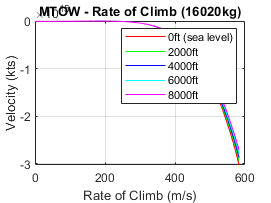

%  ROC Graph
figure(2)
plot(V_ROC, ROC_0, 'r')
hold on, grid on, grid minor
plot(V_ROC, ROC_2000, 'g')
plot(V_ROC, ROC_4000, 'b')
plot(V_ROC, ROC_6000, 'c')
plot(V_ROC, ROC_8000, 'm')
title('MTOW - Rate of Climb (16020kg)')
xlabel ('Rate of Climb (m/s)')
ylabel ('Velocity (kts)')
legend ('0ft (sea level)', '2000ft', '4000ft', '6000ft', '8000ft')

## **Cruise Performance**

Altitude

% Air Density at Different Altitudes (kg/m^3)
Ad_18000 = 0.6985011138848998;
Ad_20000 = 0.653120807146471;
Ad_22000 = 0.6100311406705187;
Ad_24000 = 0.5691520221401728;
Ad_26000 = 0.5304193777019374;

% Temperature at Different Altitudes (Kelvin)
T_18000 = 252.5;
T_20000 = 248.6;
T_22000 = 244.6;
T_24000 = 240.7;
T_26000 = 236.7;

% Speed of Sound at Different Altitudes (m/s)
SS_18000 = 295 ; %318.560704
SS_20000 = 289.3;%316.05728;
SS_22000 = 283.4;%313.531504;
SS_24000 = 277.4 %310.98784639999997;

SS_24000 = 277.4000

SS_26000 = 308.4218368;

% Fixed Perameters
Re        = 55000000 % Reynalds number

Re = 55000000

e         = (1.78 * (1 - (0.045 * (ArW^0.68)))) - 0.64; % Oswalds Efficency Factor
k         = 1/(pi * ArW * e); % Ground induced drag
GR_Cl     = 0.035; % Ground run lift coefficient on dry asphalt
LcH       = 35 * 0.3048; % lift off Clearance height
Power     = 1625000 * 2; % Power of both engines (W)
CClmax    = 0.921; % Maximum lift Coefficient (Javafoil)
CClmin    = GR_Cl/(2 * k); % Mimimum Ground run lift coefficient
CClmin_3D = (CClmin/(1+(CClmin/(pi * ArW * e)))); % Minimum 3D Coefficient of lift 
CClmax_3D = (CClmax/(1+(CClmax/(pi * ArW * e)))) % Maximum 3d Coefficient of lift

CClmax_3D = 0.8893

CCldelta  = CClmax_3D - CClmin_3D; % Differnce between Max and Min Lift Coefficient
CCd_0     = 0.03679; % Coefficient of drag at 0 Deg flap Deflection (Javafoil)
CCd       = CCd_0 + (k*(CClmax^2)); % Drag
V_Cruise  = linspace (0,300,1000) ; % Velocity at Rate of climb (m/s)

% Cruise Mach number 
MCruise_18000 = V_Cruise / SS_18000 % 18000ft

MCruise_18000 =          0    0.0010    0.0020    0.0031    0.0041    0.0051    0.0061    0.0071    0.0081    0.0092    0.0102    0.0112    0.0122    0.0132    0.0143    0.0153    0.0163    0.0173    0.0183    0.0193    0.0204    0.0214    0.0224    0.0234    0.0244    0.0254    0.0265    0.0275    0.0285    0.0295    0.0305    0.0316    0.0326    0.0336    0.0346    0.0356    0.0366    0.0377    0.0387    0.0397    0.0407    0.0417    0.0428    0.0438    0.0448    0.0458    0.0468    0.0478    0.0489    0.0499


MCruise_20000 = V_Cruise / SS_20000 % 20000ft

MCruise_20000 =          0    0.0010    0.0021    0.0031    0.0042    0.0052    0.0062    0.0073    0.0083    0.0093    0.0104    0.0114    0.0125    0.0135    0.0145    0.0156    0.0166    0.0176    0.0187    0.0197    0.0208    0.0218    0.0228    0.0239    0.0249    0.0260    0.0270    0.0280    0.0291    0.0301    0.0311    0.0322    0.0332    0.0343    0.0353    0.0363    0.0374    0.0384    0.0394    0.0405    0.0415    0.0426    0.0436    0.0446    0.0457    0.0467    0.0477    0.0488    0.0498    0.0509


MCruise_22000 = V_Cruise / SS_22000 % 22000ft

MCruise_22000 =          0    0.0011    0.0021    0.0032    0.0042    0.0053    0.0064    0.0074    0.0085    0.0095    0.0106    0.0117    0.0127    0.0138    0.0148    0.0159    0.0170    0.0180    0.0191    0.0201    0.0212    0.0223    0.0233    0.0244    0.0254    0.0265    0.0276    0.0286    0.0297    0.0307    0.0318    0.0328    0.0339    0.0350    0.0360    0.0371    0.0381    0.0392    0.0403    0.0413    0.0424    0.0434    0.0445    0.0456    0.0466    0.0477    0.0487    0.0498    0.0509    0.0519


MCruise_24000 = V_Cruise / SS_24000 % 24000ft

MCruise_24000 =          0    0.0011    0.0022    0.0032    0.0043    0.0054    0.0065    0.0076    0.0087    0.0097    0.0108    0.0119    0.0130    0.0141    0.0152    0.0162    0.0173    0.0184    0.0195    0.0206    0.0217    0.0227    0.0238    0.0249    0.0260    0.0271    0.0281    0.0292    0.0303    0.0314    0.0325    0.0336    0.0346    0.0357    0.0368    0.0379    0.0390    0.0401    0.0411    0.0422    0.0433    0.0444    0.0455    0.0465    0.0476    0.0487    0.0498    0.0509    0.0520    0.0530


MCruise_26000 = V_Cruise / SS_26000 % 26000ft

MCruise_26000 =          0    0.0010    0.0019    0.0029    0.0039    0.0049    0.0058    0.0068    0.0078    0.0088    0.0097    0.0107    0.0117    0.0127    0.0136    0.0146    0.0156    0.0166    0.0175    0.0185    0.0195    0.0204    0.0214    0.0224    0.0234    0.0243    0.0253    0.0263    0.0273    0.0282    0.0292    0.0302    0.0312    0.0321    0.0331    0.0341    0.0351    0.0360    0.0370    0.0380    0.0389    0.0399    0.0409    0.0419    0.0428    0.0438    0.0448    0.0458    0.0467    0.0477



MC_array = [MCruise_18000, MCruise_20000,MCruise_22000, MCruise_24000, MCruise_26000] % Cruise Mach number array

MC_array =          0    0.0010    0.0020    0.0031    0.0041    0.0051    0.0061    0.0071    0.0081    0.0092    0.0102    0.0112    0.0122    0.0132    0.0143    0.0153    0.0163    0.0173    0.0183    0.0193    0.0204    0.0214    0.0224    0.0234    0.0244    0.0254    0.0265    0.0275    0.0285    0.0295    0.0305    0.0316    0.0326    0.0336    0.0346    0.0356    0.0366    0.0377    0.0387    0.0397    0.0407    0.0417    0.0428    0.0438    0.0448    0.0458    0.0468    0.0478    0.0489    0.0499



% Propeller Efficieny
CPropE_18000   = (2.97984 * MCruise_18000) - (6.92675 * MCruise_18000.^2) + (19.1836 * MCruise_18000.^3) - (20.94595 * MCruise_18000.^4) % 18000ft

CPropE_18000 =          0    0.0030    0.0060    0.0090    0.0120    0.0150    0.0179    0.0209    0.0238    0.0267    0.0296    0.0325    0.0354    0.0383    0.0411    0.0440    0.0468    0.0496    0.0524    0.0552    0.0580    0.0607    0.0635    0.0662    0.0689    0.0717    0.0744    0.0771    0.0797    0.0824    0.0851    0.0877    0.0904    0.0930    0.0956    0.0982    0.1008    0.1034    0.1060    0.1085    0.1111    0.1136    0.1162    0.1187    0.1212    0.1237    0.1262    0.1287    0.1312    0.1337


CPropE_20000   = (2.97984 * MCruise_20000) - (6.92675 * MCruise_20000.^2) + (19.1836 * MCruise_20000.^3) - (20.94595 * MCruise_20000.^4) % 20000ft

CPropE_20000 =          0    0.0031    0.0062    0.0092    0.0123    0.0153    0.0183    0.0213    0.0243    0.0272    0.0302    0.0331    0.0361    0.0390    0.0419    0.0448    0.0477    0.0505    0.0534    0.0562    0.0590    0.0619    0.0647    0.0674    0.0702    0.0730    0.0757    0.0785    0.0812    0.0839    0.0866    0.0893    0.0920    0.0947    0.0973    0.1000    0.1026    0.1053    0.1079    0.1105    0.1131    0.1157    0.1183    0.1208    0.1234    0.1259    0.1285    0.1310    0.1335    0.1360


CPropE_22000   = (2.97984 * MCruise_22000) - (6.92675 * MCruise_22000.^2) + (19.1836 * MCruise_22000.^3) - (20.94595 * MCruise_22000.^4) % 22000ft

CPropE_22000 =          0    0.0031    0.0063    0.0094    0.0125    0.0156    0.0187    0.0217    0.0248    0.0278    0.0308    0.0338    0.0368    0.0398    0.0427    0.0457    0.0486    0.0515    0.0544    0.0573    0.0602    0.0631    0.0659    0.0688    0.0716    0.0744    0.0772    0.0800    0.0828    0.0856    0.0883    0.0911    0.0938    0.0965    0.0992    0.1019    0.1046    0.1073    0.1100    0.1126    0.1153    0.1179    0.1205    0.1231    0.1257    0.1283    0.1309    0.1335    0.1360    0.1386


CPropE_24000   = (2.97984 * MCruise_24000) - (6.92675 * MCruise_24000.^2) + (19.1836 * MCruise_24000.^3) - (20.94595 * MCruise_24000.^4) % 24000ft

CPropE_24000 =          0    0.0032    0.0064    0.0096    0.0128    0.0159    0.0191    0.0222    0.0253    0.0284    0.0315    0.0345    0.0376    0.0406    0.0436    0.0466    0.0496    0.0526    0.0556    0.0585    0.0615    0.0644    0.0673    0.0702    0.0731    0.0759    0.0788    0.0816    0.0845    0.0873    0.0901    0.0929    0.0957    0.0985    0.1012    0.1040    0.1067    0.1094    0.1121    0.1148    0.1175    0.1202    0.1229    0.1255    0.1282    0.1308    0.1335    0.1361    0.1387    0.1413


CPropE_26000   = (2.97984 * MCruise_26000) - (6.92675 * MCruise_26000.^2) + (19.1836 * MCruise_26000.^3) - (20.94595 * MCruise_26000.^4) % 26000ft

CPropE_26000 =          0    0.0029    0.0058    0.0086    0.0115    0.0143    0.0172    0.0200    0.0228    0.0256    0.0284    0.0311    0.0339    0.0366    0.0394    0.0421    0.0448    0.0475    0.0502    0.0529    0.0555    0.0582    0.0608    0.0635    0.0661    0.0687    0.0713    0.0739    0.0765    0.0790    0.0816    0.0841    0.0867    0.0892    0.0917    0.0942    0.0967    0.0992    0.1017    0.1042    0.1066    0.1091    0.1115    0.1140    0.1164    0.1188    0.1212    0.1236    0.1260    0.1284



CPE_array = [CPropE_18000, CPropE_20000, CPropE_22000, CPropE_24000, CPropE_26000]

CPE_array =          0    0.0030    0.0060    0.0090    0.0120    0.0150    0.0179    0.0209    0.0238    0.0267    0.0296    0.0325    0.0354    0.0383    0.0411    0.0440    0.0468    0.0496    0.0524    0.0552    0.0580    0.0607    0.0635    0.0662    0.0689    0.0717    0.0744    0.0771    0.0797    0.0824    0.0851    0.0877    0.0904    0.0930    0.0956    0.0982    0.1008    0.1034    0.1060    0.1085    0.1111    0.1136    0.1162    0.1187    0.1212    0.1237    0.1262    0.1287    0.1312    0.1337


180000ft

% 100% Throttle 
Pa18000_100 = (CPropE_18000 * (Ad_18000/Ad_0) * Power)  % Power avalible 

Pa18000_100 = 1.0e+07 *

         0    0.0006    0.0011    0.0017    0.0022    0.0028    0.0033    0.0039    0.0044    0.0050    0.0055    0.0060    0.0066    0.0071    0.0076    0.0081    0.0087    0.0092    0.0097    0.0102    0.0107    0.0113    0.0118    0.0123    0.0128    0.0133    0.0138    0.0143    0.0148    0.0153    0.0158    0.0163    0.0167    0.0172    0.0177    0.0182    0.0187    0.0192    0.0196    0.0201    0.0206    0.0211    0.0215    0.0220    0.0225    0.0229    0.0234    0.0239    0.0243    0.0248


Pr18000_100 = 0.5 * Ad_18000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_18000 .* V_Cruise * WingA))) % Power Required

Pr18000_100 = 1.0e+08 *

       Inf    2.8059    1.4029    0.9353    0.7015    0.5612    0.4676    0.4008    0.3507    0.3118    0.2806    0.2551    0.2338    0.2158    0.2004    0.1871    0.1754    0.1651    0.1559    0.1477    0.1403    0.1336    0.1275    0.1220    0.1169    0.1122    0.1079    0.1039    0.1002    0.0968    0.0935    0.0905    0.0877    0.0850    0.0825    0.0802    0.0779    0.0758    0.0738    0.0720    0.0702    0.0684    0.0668    0.0653    0.0638    0.0624    0.0610    0.0597    0.0585    0.0573



% 90% Throttle
Pa18000_90 = (CPropE_18000 * (Ad_18000/Ad_0) * Power) * 0.9; % Power avalible 
Pr18000_90 = 0.5 * Ad_18000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_18000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa18000_80 = (CPropE_18000 * (Ad_18000/Ad_0) * Power) * 0.8; % Power avalible 
Pr18000_80 = 0.5 * Ad_18000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_18000 .* V_Cruise * WingA))); % Power Required

% Graph showing Power Vs Velovity at 100% Throttle
%figure (3)
%grid on, hold on 
%plot(V_Cruise, Pr18000_100, 'r', V_Cruise, Pa18000_100, '--', 'Color', 'r')
%plot(V_Cruise, Pr20000_100, 'g', V_Cruise, Pa20000_100, '--', 'Color', 'g')
%plot(V_Cruise, Pr22000_100, 'b', V_Cruise, Pa22000_100, '--', 'Color', 'b')
%plot(V_Cruise, Pr24000_100, 'c', V_Cruise, Pa24000_100, '--', 'Color', 'c')
%plot(V_Cruise, Pr26000_100, 'm', V_Cruise, Pa26000_100, '--', 'Color', 'm')
%title('Power Vs Velovity at 100% Throttle (MTOW)')
%xlabel('Power (W)')
%ylable('Velocity (kts)')
%legend('18000ft', '20000ft', '22000', '24000', '26000')


200000ft

% 100% Throttle 
Pa20000_100 = (CPropE_20000 * (Ad_20000/Ad_0) * Power); % Power avalible 
Pr20000_100 = 0.5 * Ad_20000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_20000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa20000_90 = (CPropE_20000 * (Ad_20000/Ad_0) * Power) * 0.9; % Power avalible 
Pr20000_90 = 0.5 * Ad_20000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_20000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa20000_80 = (CPropE_20000 * (Ad_20000/Ad_0) * Power) * 0.8; % Power avalible 
Pr20000_80 = 0.5 * Ad_20000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_20000 .* V_Cruise * WingA))); % Power Required

22000ft

% 100% Throttle 
Pa22000_100 = (CPropE_22000 * (Ad_22000/Ad_0) * Power); % Power avalible 
Pr22000_100 = 0.5 * Ad_22000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_22000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa22000_90 = (CPropE_22000 * (Ad_22000/Ad_0) * Power) * 0.9; % Power avalible 
Pr22000_90 = 0.5 * Ad_22000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_22000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa22000_80 = (CPropE_22000 * (Ad_22000/Ad_0) * Power) * 0.8; % Power avalible 
Pr22000_80 = 0.5 * Ad_22000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_22000 .* V_Cruise * WingA))); % Power Required

24000ft

% 100% Throttle 
Pa24000_100 = (CPropE_24000 * (Ad_24000/Ad_0) * Power); % Power avalible 
Pr24000_100 = 0.5 * Ad_24000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_24000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa24000_90 = (CPropE_24000 * (Ad_24000/Ad_0) * Power) * 0.9; % Power avalible 
Pr24000_90 = 0.5 * Ad_24000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_24000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa24000_80 = (CPropE_24000 * (Ad_24000/Ad_0) * Power) * 0.8; % Power avalible 
Pr24000_80 = 0.5 * Ad_24000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_24000 .* V_Cruise * WingA))); % Power Required

26000ft

% 100% Throttle 
Pa26000_100 = (CPropE_26000 * (Ad_26000/Ad_0) * Power); % Power avalible 
Pr26000_100 = 0.5 * Ad_26000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_26000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa26000_90 = (CPropE_26000 * (Ad_26000/Ad_0) * Power) * 0.9; % Power avalible 
Pr26000_90 = 0.5 * Ad_26000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_26000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa26000_80 = (CPropE_26000 * (Ad_26000/Ad_0) * Power) * 0.8; % Power avalible 
Pr26000_80 = 0.5 * Ad_26000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_26000 .* V_Cruise * WingA))); % Power Required

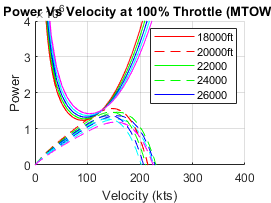

% Graph showing Power Vs Velovity at 100% Throttle
figure (3)
grid on, hold on 
plot(V_Cruise, Pr18000_100, 'r', V_Cruise, Pa18000_100, '--', 'Color', 'r')
plot(V_Cruise, Pr20000_100, 'g', V_Cruise, Pa20000_100, '--', 'Color', 'g')
plot(V_Cruise, Pr22000_100, 'b', V_Cruise, Pa22000_100, '--', 'Color', 'b')
plot(V_Cruise, Pr24000_100, 'c', V_Cruise, Pa24000_100, '--', 'Color', 'c')
plot(V_Cruise, Pr26000_100, 'm', V_Cruise, Pa26000_100, '--', 'Color', 'm')
title('Power Vs Velocity at 100% Throttle (MTOW)')
xlabel('Velocity (kts)')
ylabel('Power')
legend('18000ft', '20000ft', '22000', '24000', '26000')

xlim([0 400])
ylim([0 4000000])

Range Profile